## Simulation Gabelstapler Gruppe A10

Autoren: Philip Reußner, Florian Gerke, Zoe Stiehl, Niklas Reitter, Manuel Baier

### Definitionen Parameter:

clear % Workspace Variablen löschen

%%% Allgemein
g = 9.81; % gravitationskonstante [m/s^2]
m_fz = 161; % masse fahrzeug teilsystem [kg]
m_mast = 95; % masse mast teilsystem [kg]
m_g = 30 +100; % masse gabel + last [kg]

y_m_fz = 0.5; % y pos schwerpunkt fahrzeug teilsystem [m] #TODO
y_m_mast = 2; % y pos schwerpunkt mast teilsystem [m] #TODO
y_m_g = 6.2; % y pos schwerpunkt gabel + last [m] #TODO

%%% Antrieb
L_Motor = 0.45e-3; % induktivität [H]
R_Motor = 0.07; % eigenwiderstand [Ohm]
k_Motor = 0.119; % motorkennzahl [N*m/A]
k_e = 0.119; % elektrische konstante?, umrechnungskonstante #TODO [V/(rad/s)]
theta_motor = 0.0000652; % Trägheit des Motors [kg*m^2]

i_Getriebe = 7; % Übersetzung Getriebe
theta_getriegbe = 0.0001; % Massenträgheitsmoment Getriebe [kg*m^2]
d_gtr = 0.015; % dämpfungskonstante getriebe 
eta_Getriebe = .95; % wirkungsgrad Getriebe

r_R = 0.114; % radius rad [m]

%%% Sensorik
k_Acc = 0.204; % steigung kennlinie accelerometer
b_Acc = 0; % offset kennlinie accelerometer

%%% Biegebalken / Mast
I_y = 2.6e-7; % flächenträgheitsmoment [m^4]
E = 71.7e9; % elastizitätsmodul
k = 258; % Ersatzfederkostante Mast ##TODO calculate here, improve estimate
d = 16.75; % Ersatzdämpferkonstante Mast ##TODO caclulate here, improve estimate

%%% Regelung
k_P = 2500; % proportionalteil
k_I = 1000; % integralteil
k_D = 500; % differentialteil

%%% Abgeleitete Parameter
theta_red = (i_Getriebe^2 * theta_motor) + theta_getriegbe  ; % reduziertes trägheitsmoment antrieb [kg*m^2]
theta_s = theta_red + m_fz * r_R^2; % Massenträgheitsmoment Fahrzeug [kg*m^2]
disp("DEBUG: load success");

DEBUG: load success


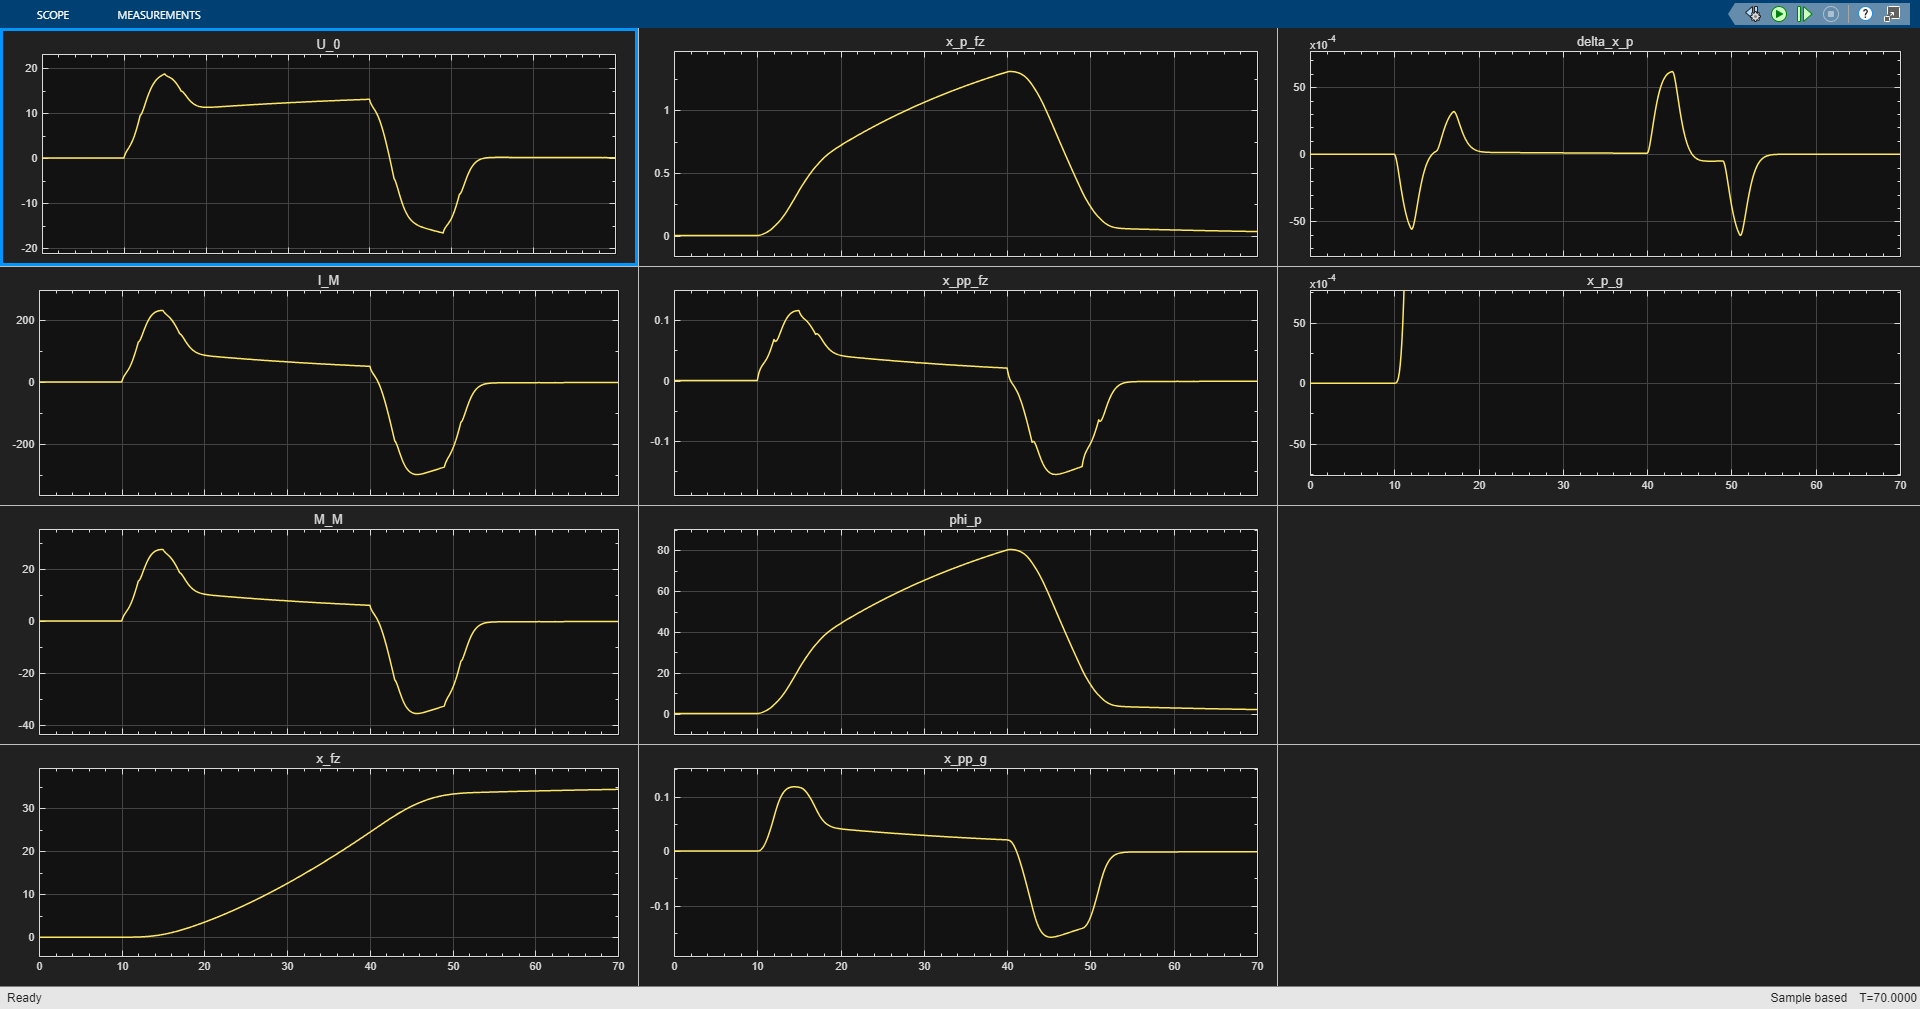

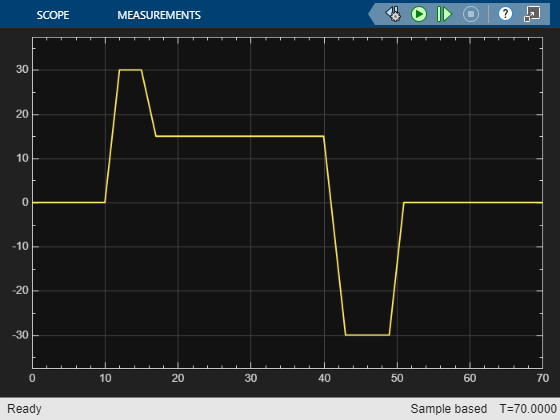


%%% Plots
% Simulationen durchfüren 
sim_geregelt = sim("gabelstapler_Simulink.slx", 0:0.1:70);

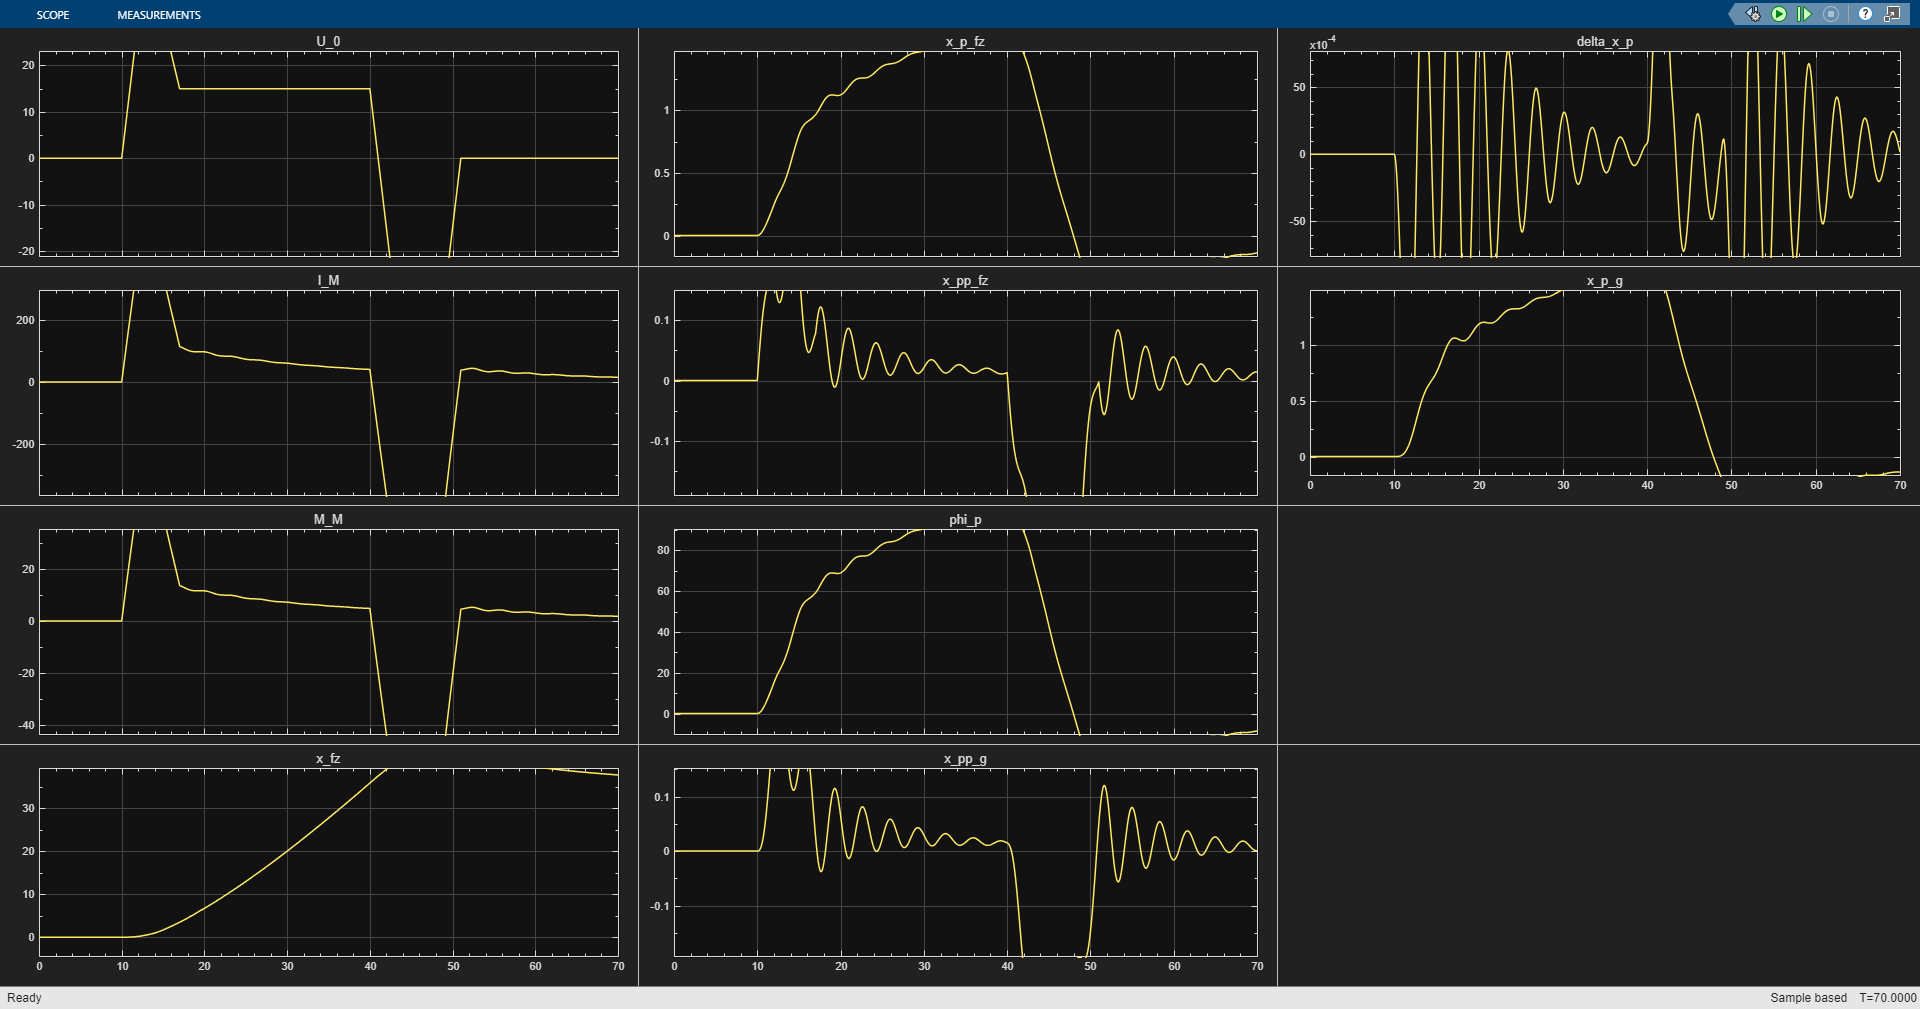

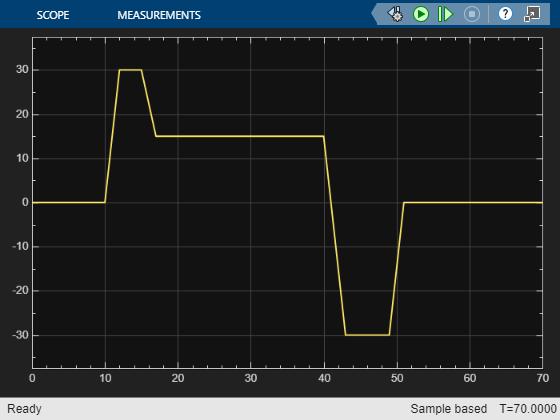

sim_ungeregelt = sim("gabelstapler_Simulink_ungeregelt.slx", 0:0.1:70);

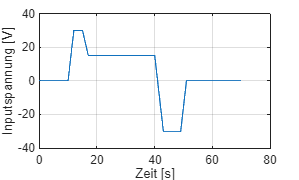


% Plot der Inputspannung
plot(sim_geregelt.ScopeData3.time, sim_geregelt.ScopeData3.signals.values);
ylabel('Inputspannung [V]');
xlabel('Zeit [s]');
% title('Inputspannung');
grid on;
ax = gca;
exportgraphics(ax,"Inputspannung.svg")

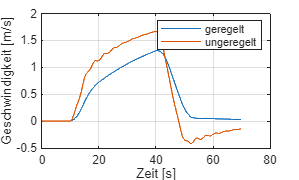


% Plot der Geschwindigkeiten vom Fahrzeug
plot(sim_geregelt.Scope_out.time, sim_geregelt.Scope_out.signals(5).values);
hold on
plot(sim_ungeregelt.Scope_out.time, sim_ungeregelt.Scope_out.signals(5).values);
legend("geregelt","ungeregelt")
ylabel('Geschwindigkeit [m/s]');
xlabel('Zeit [s]');
% title('Geschwindigkeit des Fahrzeugs');
grid on;
ax = gca;
exportgraphics(ax,"Geschwindigkeit_Fahrzeug.svg")
hold off

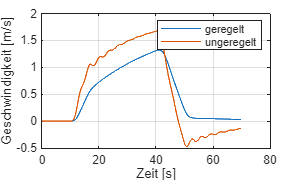


% Plot der Geschwindigkeiten der Gabel
plot(sim_geregelt.Scope_out.time, sim_geregelt.Scope_out.signals(10).values);
hold on
plot(sim_ungeregelt.Scope_out.time, sim_ungeregelt.Scope_out.signals(10).values);
legend("geregelt","ungeregelt")
ylabel('Geschwindigkeit [m/s]');
xlabel('Zeit [s]');
% title('Geschwindigkeit des Gabel');
grid on;
ax = gca;
exportgraphics(ax,"Geschwindigkeit_Gabel.svg")
hold off

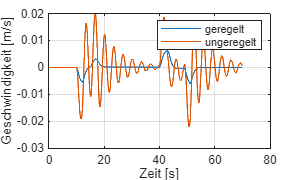


% Plot der Geschwindigkeitsunterschiede zwischen Gabel und Fahrzeug
plot(sim_geregelt.Scope_out.time, sim_geregelt.Scope_out.signals(9).values);
hold on
plot(sim_ungeregelt.Scope_out.time, sim_ungeregelt.Scope_out.signals(9).values);
legend("geregelt","ungeregelt")
ylabel('Geschwindigkeit [m/s]');
xlabel('Zeit [s]');
% title('Geschwindigkeitsunterschied Gabel Fahrzeug');
grid on;
ax = gca;
exportgraphics(ax,"Geschw_Differenz.svg")
hold off

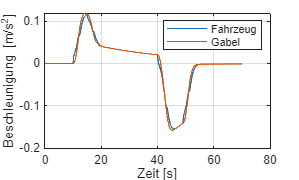


% Plot der Beschleunigungen
plot(sim_geregelt.Scope_out.time, sim_geregelt.Scope_out.signals(6).values);
hold on
plot(sim_geregelt.Scope_out.time, sim_geregelt.Scope_out.signals(8).values);
legend("Fahrzeug","Gabel")
ylabel('Beschleunigung [m/s^2]');
xlabel('Zeit [s]');
% title('Beschleunigungen mit Regelung');
grid on;
ax = gca;
exportgraphics(ax,"Beschleunigung.svg")
hold off

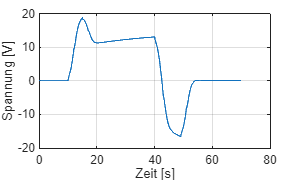


% Plot der Spannung am Motor
plot(sim_geregelt.Scope_out.time, sim_geregelt.Scope_out.signals(1).values);
ylabel('Spannung [V]');
xlabel('Zeit [s]');
% title('Spannung am Motor');
grid on;
ax = gca;
exportgraphics(ax,"Spannung_am_Motor.svg")

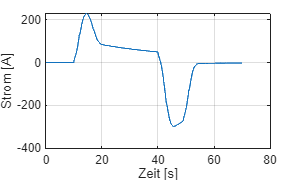


% Plot des Stroms am Motor
plot(sim_geregelt.Scope_out.time, sim_geregelt.Scope_out.signals(2).values);
ylabel('Strom [A]');
xlabel('Zeit [s]');
% title('Strom am Motor');
grid on;
ax = gca;
exportgraphics(ax,"Strom_am_Motor.svg")

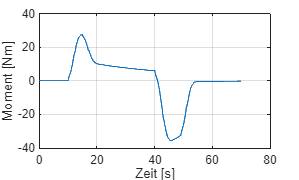


% Plot des Motormoments
plot(sim_geregelt.Scope_out.time, sim_geregelt.Scope_out.signals(3).values);
ylabel('Moment [Nm]');
xlabel('Zeit [s]');
% title('Motormoment');
grid on;
ax = gca;
exportgraphics(ax,"Motormoment.svg")